# Predicting Future Electricity Usage

## Residential Usage

Set parameters for the analysis: residential usage, cubic polynomial fit, and predict usage for Jan 2020.

Predicted Residential usage in Jan 2020 is 3316784.776 MWh/day


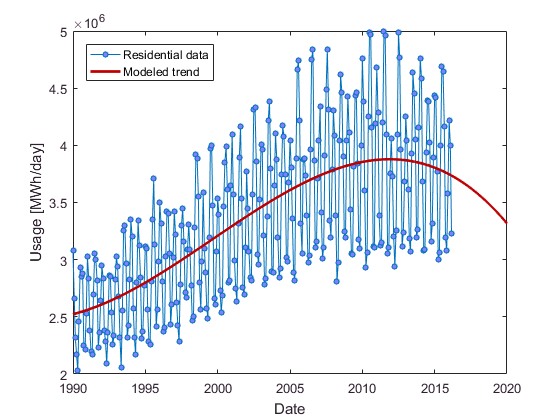

datafile = 'C:\class\coursefiles\mlbe\electricity\elec_res.xlsx';
polydegree = 3;
predictdate = datetime(2020,1,1);

predicteduse = polyPrediction(datafile,polydegree,predictdate);

Predicted Residential usage in Jan 2020 is 3906022.0073 MWh/day


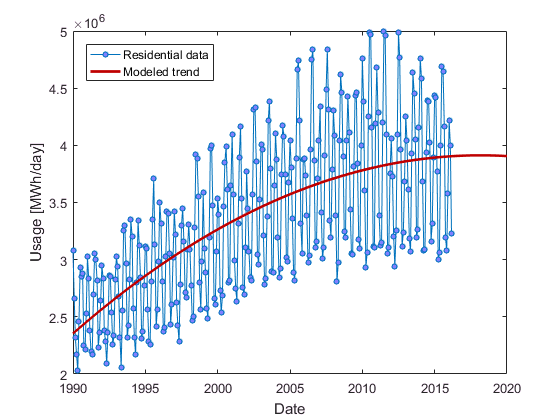

predicteduse = polyPrediction(datafile,2,predictdate);

Predicted Residential usage in Jan 2050 is 1922825.5977 MWh/day


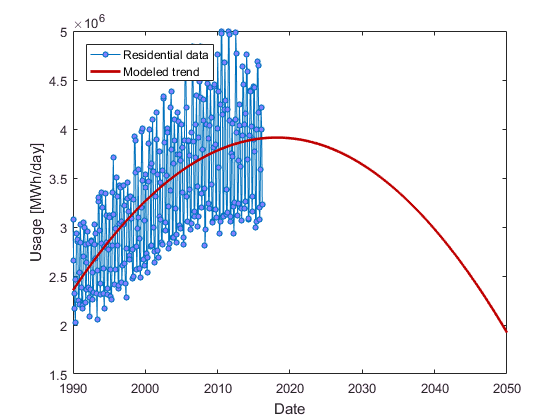

predicteduse = polyPrediction(datafile,2,datetime(2050,1,1));

function predictedusage = polyPrediction(datafile,polydegree,predictdate)

Import electricity usage data (with NaNs).

data = readtable(datafile);
sector = data.Properties.VariableNames{2};
usage = data{:,2};
dates = data.Date;

Normalize data from monthly usage to average daily usage.

d = dates;
d(end+1) = d(end) + calmonths(1);
daysInMth = days(diff(d));
usage = usage./daysInMth; % per-day usage

Fill in the missing values.

usage = fillmissing(usage,'spline');

Find the polynomial fit, then evaluate the model through to the prediction date.

elapsedYears = years(dates - dates(1));
c = polyfit(elapsedYears,usage,polydegree);

endDuration = years(predictdate - dates(1));
elYrFit = linspace(0,endDuration,501);
usageFit = polyval(c,elYrFit);
predictedusage = usageFit(end);

Display the predicted usage.

predictdate.Format = 'MMM yyyy';
disp(['Predicted ',sector,' usage in ',char(predictdate),...
' is ',num2str(predictedusage),' MWh/day'])

Plot the data and model together.

plot(dates,usage,'o-','MarkerSize',4,'MarkerFaceColor',[0.5 0.5 1])
hold on
datesFit = dates(1) + years(elYrFit);
plot(datesFit,usageFit,'Color',[0.75 0 0],'LineWidth',2)
hold off
xlabel('Date')
ylabel('Usage [MWh/day]')
legend([sector ' data'],'Modeled trend','Location','NW')

end